Data for Trust and drag

clear; clc;
cd('E:\DTU\7- semester\Bachelor projekt\Plots')
File_1= importdata('sunny_300kv_18x5.5_22V.txt');
ESC=File_1.data(:,1);
RPSa=File_1.data(:,2);
RPSb=File_1.data(:,3);
V=File_1.data(:,4);
I=File_1.data(:,5);
T=File_1.data(:,6);

%Trust---------------------------------------------------------------------
omega=2*pi.*RPSa;
g=9.82*1e-3;
F=g.*T;

From=50:50:850

From =     50   100   150   200   250   300   350   400   450   500   550   600   650   700   750   800   850


ESC_New=1.05:0.05:1.85

ESC_New =     1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500


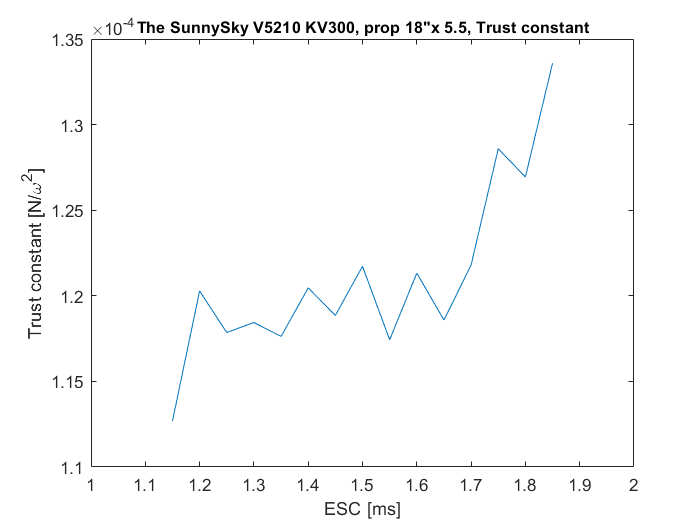


TC=F./omega.^2;

figure
plot(ESC_New(3:length(ESC_New)),TC(3:length(TC)))
xlabel('ESC [ms]')
ylabel('Trust constant [N/\omega^2]')
xlim([1 2])
title('The SunnySky V5210 KV300, prop 18"x 5.5, Trust constant','FontSize',9.8)


TrustConstant=mean(TC(3:length(TC)))

TrustConstant = 1.2108e-04

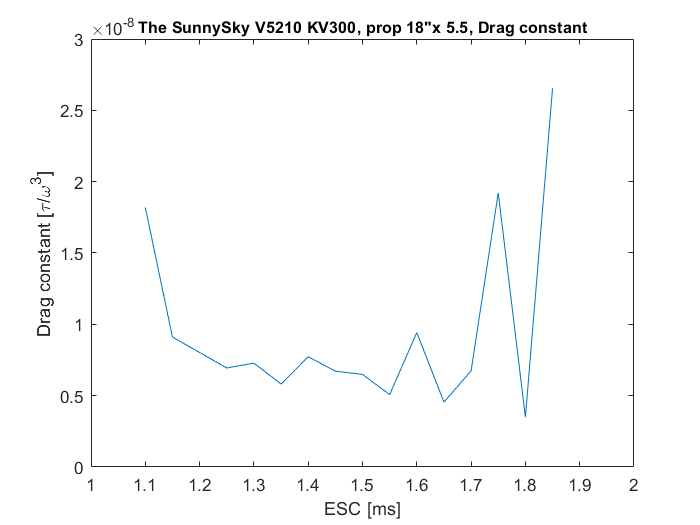


%Drag---------------------------------------------------------------------
Kv = 300; % [RPM pr volt]
Km = 60/(Kv * 2 * pi);
DC=Km*diff(I)./diff(omega.^3);

figure
plot(ESC_New(2:end),DC(1:length(DC)))
xlabel('ESC [ms]')
ylabel('Drag constant [\tau/\omega^3]')
%xticks(ESC_New(3:length(ESC_New)))
xlim([1 2])
title('The SunnySky V5210 KV300, prop 18"x 5.5, Drag constant','FontSize',9.8)


DragConstant=mean(DC(2:length(DC)))

DragConstant = 8.8779e-09

clear; clc;
cd('E:\DTU\7- semester\Bachelor projekt\Plots');
File_2= importdata('sunny300_18in_motor_step_03.txt');
Time=File_2.data(:,1)/1000;
RPSa=File_2.data(:,2);
RPSb=File_2.data(:,3);
ESC=File_2.data(:,4);
V=File_2.data(:,5);
I=File_2.data(:,6);

ESC_New=ESC/1000+1


figure(1)
subplot(2,2,1);
plot(Time,ESC_New,'r')
title('ESC [ms]')
xlabel('Time [s]')
hold on
subplot(2,2,2);
plot(Time,RPSa,'g')
title('RPS (Rotations per second)')
xlabel('Time [s]')
hold on
subplot(2,2,[3,4])
plot(Time,I,'b');
title('Motor current [A]')
xlabel('Time [s]')
hold off;

figure(2)
plot(Time,ESC/10,'r')
hold on
plot(Time,RPSa,'g')
hold on
plot(Time,I*3,'b');
hold off;
legend('ESC [ms]','RPS (Rotations per second)','Motor current [A]','Location','northwest')
xlabel('Time [s]');
ylabel('ESC [ms] (from 1 to 2ms)');
yticklabels([1:0.1:2]);
title('The SunnySky V5210 KV300, prop 18"x 5.5, 22V, Time performance','FontSize',10)